# Konzeptfahrzeug HElmar - Auslegung Radnabenantrieb

*Prof. Dr.-Ing. Ralf Schuler, Esslingen University, 2.11.2022*

Betrachtet wird der elektrische Radnabenantrieb des Konzeptfahrzeugs HElmar.

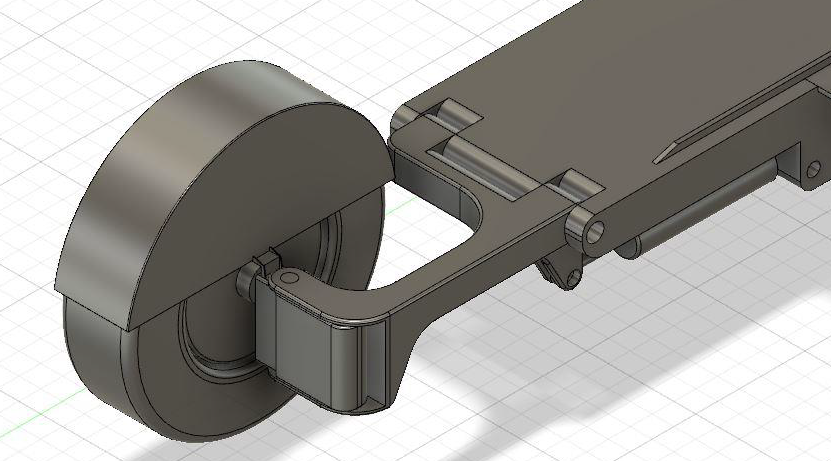

## Verwendete Antriebsmotor(en)

Es sollen Radnabenantriebe von QS Motors verwendet werden. Ganaue Bezeichnung: QS Motor 8000 273 50H V3 E-Auto Hub Motor

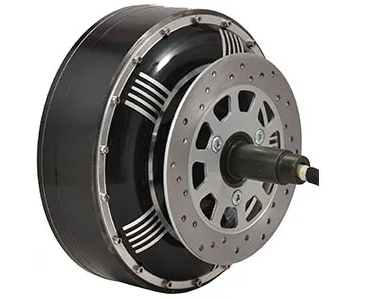

Weitere Informationen unter: 

- [http://www.qs-motor.com/product/3000w-8000w-electric-car-hub-motor273-model/](http://www.qs-motor.com/product/3000w-8000w-electric-car-hub-motor273-model/)

- [http://www.cnqsmotor.com/en/article_read/QS%20273%208KW%2050H%20V3%20E-Car%20Single%20Shaft%20Hub%20Motor/274.html](http://www.cnqsmotor.com/en/article_read/QS%20273%208KW%2050H%20V3%20E-Car%20Single%20Shaft%20Hub%20Motor/274.html)

- [https://www.miromax.lt/en/m-6/c-26/c-49-electric_car_conversion_kits/product-783-qs-273_8000w_electric_motor_for_car#product](https://www.miromax.lt/en/m-6/c-26/c-49-electric_car_conversion_kits/product-783-qs-273_8000w_electric_motor_for_car#product)

### Gegebene Motordaten

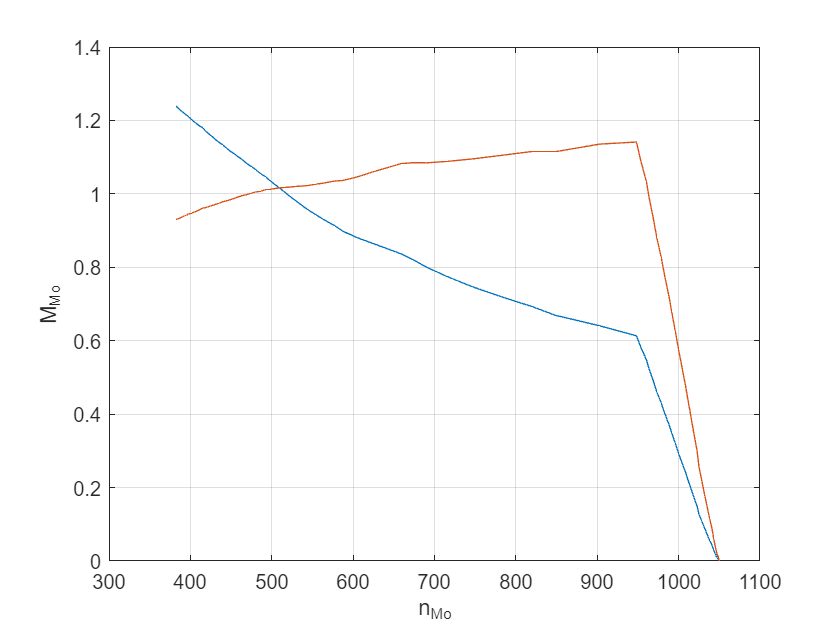

trqMotRefCont = 150; %[Nm]
pwrMotRefCont = 8000; %[W]
volMotRef = 72; %[V]
massMot = 23; %[kg]

% Messkurven aus Datenblatt
load('QS273.mat')
pwrOutMotRef=cell2mat(W50H273V3Measurement72V(2:(end-1),6));
pwrInMotRef=cell2mat(W50H273V3Measurement72V(2:(end-1),4));
trqMotRef=cell2mat(W50H273V3Measurement72V(2:(end-1),5));
speedMotRef_rpm=cell2mat(W50H273V3Measurement72V(2:(end-1),1));
effMotRef=cell2mat(W50H273V3Measurement72V(2:(end-1),7));
curMotRef=cell2mat(W50H273V3Measurement72V(2:(end-1),2));

figure
plot(speedMotRef_rpm,trqMotRef./trqMotRefCont)
hold on
grid on
plot(speedMotRef_rpm,pwrOutMotRef./pwrMotRefCont)
xlabel('n_{Mo}')
ylabel('M_{Mo}')

### Generierung eines adäquaten Motorkennfeldes

Der verfügbare Datensatz ist für 72V gemessen. Anpassung der Daten auf HElmar Batteriespannung von ca. 48V erforderlich.

Ermittlung kv-Faktors (constMotVol_rpVmin) anhand der gemessenen 72V Kennlinie:

speedMotNoLoad72V_rpm = max(speedMotRef_rpm)

speedMotNoLoad72V_rpm = 1.0506e+03

constMotVol_rpVmin = speedMotNoLoad72V_rpm/volMotRef

constMotVol_rpVmin = 14.5917

Drehmomentenkonstante aus kv (=constMotVol_rpVmin):

constMotTrq = volMotRef/(2*pi/60*speedMotNoLoad72V_rpm)

constMotTrq = 0.6544

Ermittlung des Ankerwiderstands $R_A$ anhand der gemessenen 72V Kennlinie und den Daten am "Endpunkt" der Leistungshyperbel.

Aus $M_{Mo}=\frac{U_A}{R_A}\cdot c_{Mo} - \frac{c_{Mo}^2}{R_A}\cdot \omega_{Mo}$  folgt $R_A = \frac{c_{Mo}^2}{\Delta M}\cdot \frac{\pi \cdot \Delta n}{30}$. Letzteres entspricht $R_A=\frac{U_i}{I}$.

trqMotRef72V = 92; % abgelesen aus gemessener Kennlinie
speedMotRef72V = 948.2; % abgelesen aus gemessener Kennlinie
resMot = (constMotTrq^2/trqMotRef72V)*(pi/30*(speedMotNoLoad72V_rpm-speedMotRef72V))

resMot = 0.0499

resMotPh2Ph = 0.016; % gegeben auf https://endless-sphere.com/forums/viewtopic.php?t=80635

Anpassung des Kennfeldes auf nominelle Spannung:

volMotNom = 48; % Auslegungspannung

speedMotNoLoadNom_rpm = 30/pi*volMotNom/constMotTrq

speedMotNoLoadNom_rpm = 700.4000

trqMotStall=volMotNom/resMot*constMotTrq

trqMotStall = 629.2656

Zur Verdeutlichung: $M_{St}$=trqMotStall, $n_0$=speedMotNoLoad_rpm

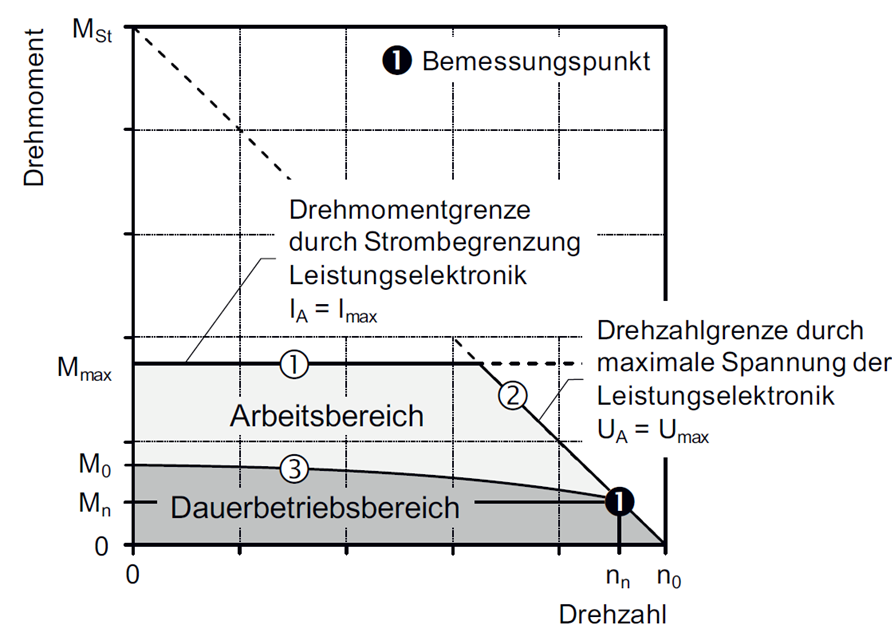

Mit der gegebenen Stromgrenzen für den Motor wird:

curMotCont = 140; % aus Datenblatt Miromax
curMotPeak = 280; % aus Datenblatt Miromax

Das Dauermoment des Motors:

trqMotCont = constMotTrq*curMotCont

trqMotCont = 91.6209

Das Überlastmoment des Motors:

trqMotPeak = constMotTrq*curMotPeak

trqMotPeak = 183.2418

Die Drehzahl bis zu welcher der Motor das Dauermoment abgeben kann:

speedMotTrqCont_rpm =(volMotNom/(2*pi*constMotTrq)-resMot/(2*pi*constMotTrq^2)*trqMotCont)*60

speedMotTrqCont_rpm = 598.4220

Die Drehzahl bis zu welcher der Motor das Überlastmoment abgeben kann:

speedMotTrqPeak_rpm =(volMotNom/(2*pi*constMotTrq)-resMot/(2*pi*constMotTrq^2)*trqMotPeak)*60

speedMotTrqPeak_rpm = 496.4439

Die maximale Leistung bei Duermoment:

pwrMotTrqMaxCont = trqMotCont*speedMotTrqCont_rpm*pi/30

pwrMotTrqMaxCont = 5.7416e+03

Die maximale Leistung bei Überlastmoment:

pwrMotTrqMaxPeak = trqMotPeak*speedMotTrqPeak_rpm*pi/30

pwrMotTrqMaxPeak = 9.5263e+03

Dadurch ergeben sich folgende Kennfelder für den Motor bei 48V

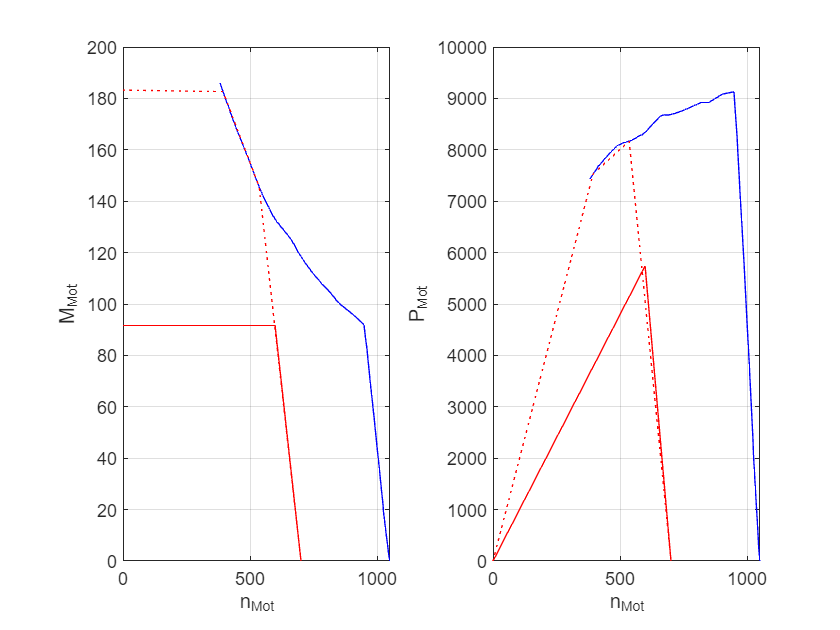

trqMotContNomPlot = [trqMotCont;trqMotCont;0]; 
trqMotPeakNomPlot = [trqMotPeak;182.6;145.6;0];% Zahlenwerte aus gemessener Kurve abgelesen
speedMotContNomPlot_rpm = [0;speedMotTrqCont_rpm;speedMotNoLoadNom_rpm];
speedMotPeakNomPlot_rpm = [0;393.7;535.8;speedMotNoLoadNom_rpm];% Zahlenwerte aus gemessener Kurve abgelesen
pwrMotContNomPlot = trqMotContNomPlot.*speedMotContNomPlot_rpm*pi/30;
pwrMotPeakNomPlot = trqMotPeakNomPlot.*speedMotPeakNomPlot_rpm*pi/30;

figure
subplot(1,2,1)
plot(speedMotRef_rpm,trqMotRef,'b',speedMotContNomPlot_rpm,trqMotContNomPlot,'r',speedMotPeakNomPlot_rpm,trqMotPeakNomPlot,'r:')
grid on
xlabel('n_{Mot}')
ylabel('M_{Mot}')
subplot(1,2,2)
plot(speedMotRef_rpm,pwrOutMotRef,'b',speedMotContNomPlot_rpm,pwrMotContNomPlot,'r',speedMotPeakNomPlot_rpm,pwrMotPeakNomPlot,'r:')
grid on
xlabel('n_{Mot}')
ylabel('P_{Mot}')

Für die Wirkungsgrade gilt allgemein


$$\eta = \frac{P_{mech}}{R\cdot I^2 + P_{mech}} = \frac{1}{ R\frac{M}{c_{Mo}^2\cdot \omega}+ 1}$$


Daraus ergibt sich ein Wirkungsgradkennfeld:

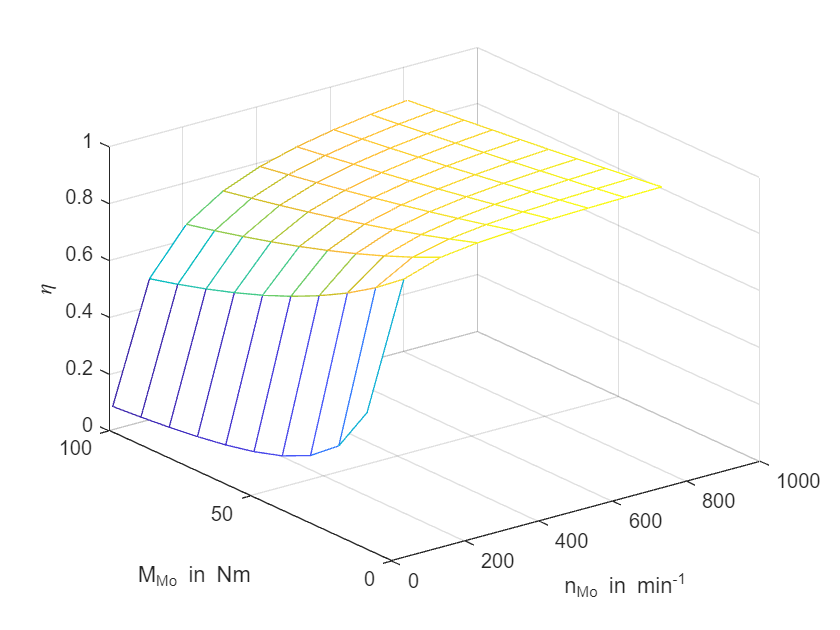

speedMotEtaPlot_rpm = [10:100:810];
trqMotEtaPlot = [10:10:100];
for i = 1:length(trqMotEtaPlot)
    for j = 1:length(speedMotEtaPlot_rpm)
        etaMap(i,j) = 1/(resMot*trqMotEtaPlot(i)/(constMotTrq^2*speedMotEtaPlot_rpm(j)*pi/30) +1);
    end
end

figure
mesh(speedMotEtaPlot_rpm,trqMotEtaPlot,etaMap)
xlabel('n_{Mo} in min^{-1}')
ylabel('M_{Mo} in Nm')
zlabel('\eta')

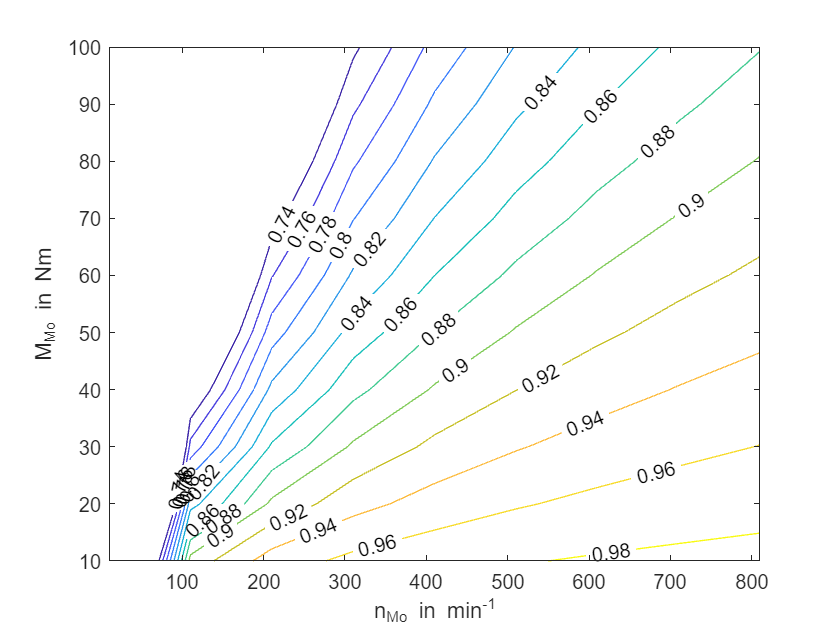

figure
contour(speedMotEtaPlot_rpm,trqMotEtaPlot,etaMap,[0.74:0.02:0.98],'ShowText','on')
xlabel('n_{Mo} in min^{-1}')
ylabel('M_{Mo} in Nm')

## Fahrleistungen

### Daten Gesamtfahrzeug

passende Felgen: [https://www.felgenshop.de/rc-design-rc30-schwarz-lackiert-18-zoll-0620071118/cupra-born-k1-alufelgen/0-0l-70kw-born-77-e-boost-95-ps/](https://www.felgenshop.de/rc-design-rc30-schwarz-lackiert-18-zoll-0620071118/cupra-born-k1-alufelgen/0-0l-70kw-born-77-e-boost-95-ps/)

massRim = 11;
g=9.81;
rhoAir=1.2;
massVeh =    800; % Abschätzung Rover: 450 kg; Batterie 190 kg, 4 QS273 Motoren a 30kg; Fahrer 75 kg; Beifahrer 65 kg; 
facRoll =    0.01;
radWheel =   0.35; % bei 18" 
facCw =      0.31;
areaVeh =    2;

%Masse Fahrgestell & 300 kg \\
%$c_w$ Wert Fahrgestell & 0,4 \\
%Stirnfläche Fahrgestell & 0,86 m\textsuperscript{2} \\
%Antriebswirkungsgrad $\eta_A$ & 0,95 \\
%Drehmassenzuschlagsfaktor $\epsilon$ & 0,0463 \\

hypothetische Geschwindigkeit bei Leerlaufdrehzahl (als Orientierungswert)

velVehHyp_kph = speedMotNoLoadNom_rpm*pi/30*radWheel*3.6

velVehHyp_kph = 92.4156

Geschwindigkeit, bis zu welcher mit Dauermoment angetrieben werden kann

velVehTrqCont_kph = speedMotTrqCont_rpm*pi/30*radWheel*3.6

velVehTrqCont_kph = 78.9599

### Fahrleistungen

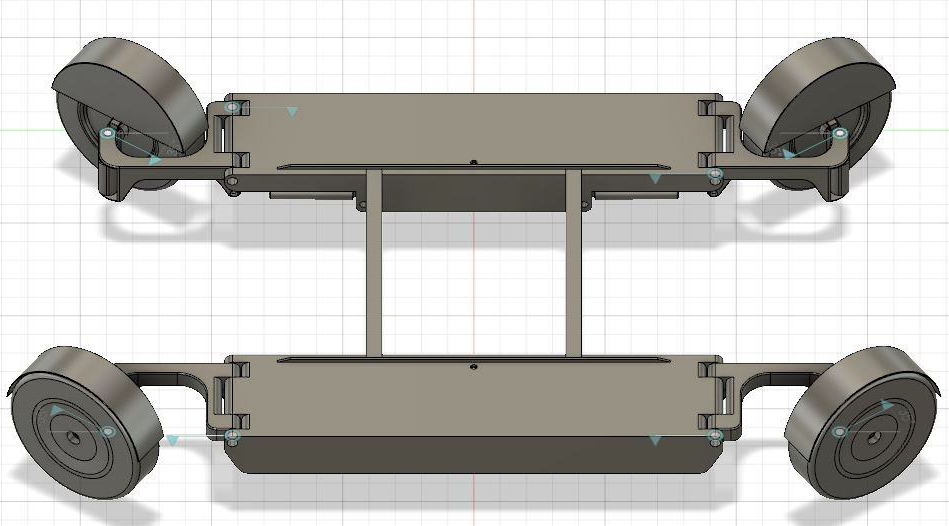

Das Fahrzeug ist mit vier Radnabenmotoren ausgerüstet.

numMot = 4;

Vollastkennlinie des gesamten Antriebs (alle vier Motoren zusammen)

figure
plot(speedMotContNomPlot_rpm,numMot*trqMotContNomPlot,'k')
grid on
ylim([0 400])
xlabel('n_{Mot}')
ylabel('M_{Mot}')
hold on

Verlauf des Normalfahrwiderstands $F_{W0}$

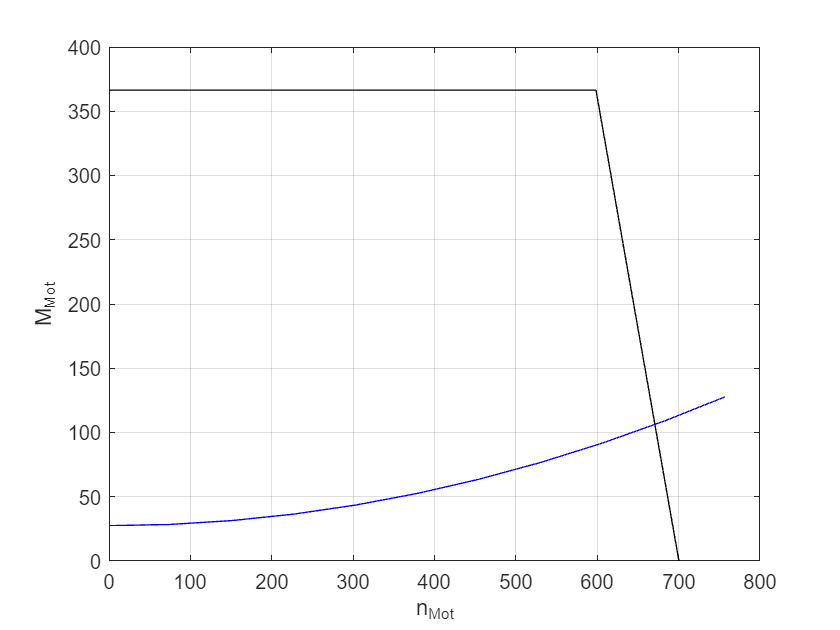

velDriveResPlot = [0:10:100]/3.6;
speedDriveResPlot_rpm = velDriveResPlot/radWheel*30/pi;
forceDriveResPlot = massVeh*g*facRoll + facCw*areaVeh*rhoAir/2*velDriveResPlot.^2;
trqDriveResPlot = forceDriveResPlot*radWheel;

plot(speedDriveResPlot_rpm,trqDriveResPlot,'b')

Beschleunigung ist zu Beginn des Anfahrvorgangs in der Ebene

accelDriveOff = (numMot*trqMotCont/radWheel - massVeh*g*facRoll)/massVeh

accelDriveOff = 1.2108

Mögliche Steigung

alphaMax = asind(((numMot*trqMotCont)/radWheel - massVeh*g*facRoll)/(massVeh*g));
q=tand(alphaMax)*100

q = 12.4373

Mögliche Steigung am Ende des konstanten Motormomentes

alpha = asind(((numMot*trqMotCont)/radWheel - massVeh*g*facRoll - facCw*areaVeh*rhoAir/2*(velVehTrqCont_kph/3.6)^2)/(massVeh*g));
q=tand(alpha)*100

q = 10.1132

## **Energieverbrauch stationärer Betriebspunkt**

Annahme: Die mittlere Fahrzeuggeschwindigkeit wird vorgegeben mit:

velVehMean_kph = 40;
velVehMean = velVehMean_kph/3.6;
speedMotMean_rpm = velVehMean/radWheel*30/pi

speedMotMean_rpm = 303.1523

accelVehMean = 0;
trqVehMean = (massVeh*accelVehMean + massVeh*g*facRoll + facCw*areaVeh*rhoAir/2*velVehMean^2)*radWheel

trqVehMean = 43.5421

Mit welcher Spannung werden die Motoren betrieben, um den Betriebspunkt zu ermöglichen?

curMotMean=1/numMot*trqVehMean/constMotTrq

curMotMean = 16.6335

volMotMean= resMot*curMotMean + constMotTrq*speedMotMean_rpm*pi/30

volMotMean = 21.6061

Leerlaufdrehzahl bei dieser Spannung

speedMotMeanNoLoad_rpm = (volMotMean*30)/(constMotTrq*pi)

speedMotMeanNoLoad_rpm = 315.2683

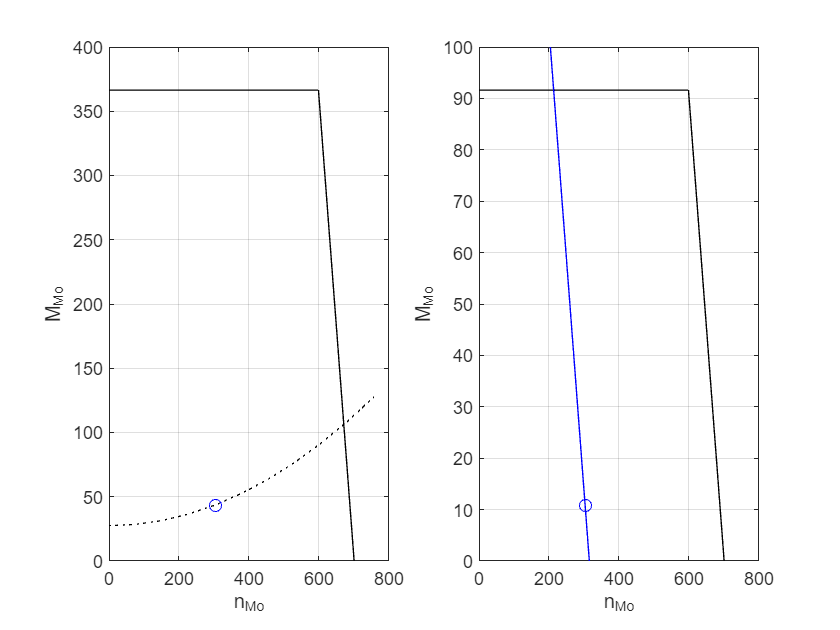

speedMotMeanPlot_rpm = [200:10:(speedMotMeanNoLoad_rpm+10)];
trqMotMeanPlot = volMotMean/resMot*constMotTrq - pi/30*constMotTrq^2/resMot*speedMotMeanPlot_rpm;

figure
subplot(1,2,1)
plot(speedMotContNomPlot_rpm,numMot*trqMotContNomPlot,'k')
hold on
plot(speedDriveResPlot_rpm,trqDriveResPlot,'k:')
grid on
ylim([0 400])
xlabel('n_{Mo}')
ylabel('M_{Mo}')
plot(speedMotMean_rpm,trqVehMean,'bo')

subplot(1,2,2)
plot(speedMotContNomPlot_rpm,trqMotContNomPlot,'k')
hold on
grid on
ylim([0 100])
xlabel('n_{Mo}')
ylabel('M_{Mo}')
plot(speedMotMean_rpm,1/numMot*trqVehMean,'bo')
%hold off
plot(speedMotMeanPlot_rpm,trqMotMeanPlot,'b')

Welchen Wirkungsgrad hat der Motor in diesem Betriebspunkt. 

pwrMotMeanElec = curMotMean*volMotMean  

pwrMotMeanElec = 359.3835

pwrMotMeanMech = 1/numMot*trqVehMean*speedMotMean_rpm*pi/30

pwrMotMeanMech = 345.5720

etaMotMean = pwrMotMeanMech/pwrMotMeanElec

etaMotMean = 0.9616

etaInv = 0.9;
etaElecDrive = etaInv*etaMotMean

etaElecDrive = 0.8654

etaBatCha = 0.9;
pwrBatMean = numMot*pwrMotMeanElec/etaElecDrive/etaBatCha

pwrBatMean = 1.8457e+03

distRange_km = 150; %[km]
timeMeanDrive = distRange_km*1000/velVehMean/3600 %[h]

timeMeanDrive = 3.7500

Energiebedarf Tank2Wheel

energyBatMean = pwrBatMean*timeMeanDrive

energyBatMean = 6.9212e+03

## **Energiebedarf Fahrzyklus**

Zur Ermittlung des Energiebedarfs wird zunächst eine Rückwärtssimulation eingesetzt.

open('EnergyDemandBackward')
load NEDC.mat

Als Fahrzyklus wird der urbane Teil des NEDC zugrunde gelegt.

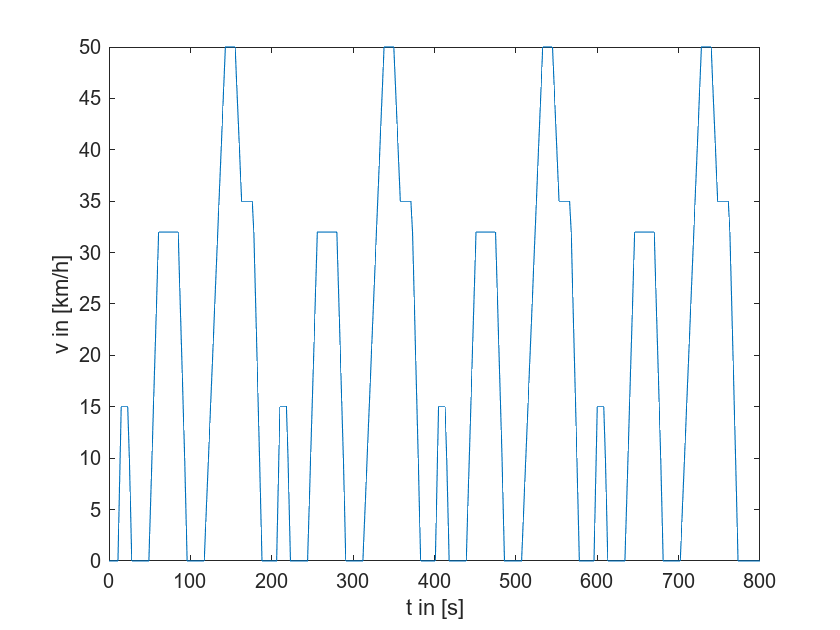

tCycle_s = t_NEDC_s(1:801); % nur urbaner Anteil
velCycle_kph = v_NEDC_kph(1:801);

figure
plot(tCycle_s,velCycle_kph)
xlabel('t in [s]')
ylabel('v in [km/h]')

Die Rekuperationseffizienz beträgt:

etaRec =     0.6 % Rekuperationseffizienz

etaRec = 0.6000

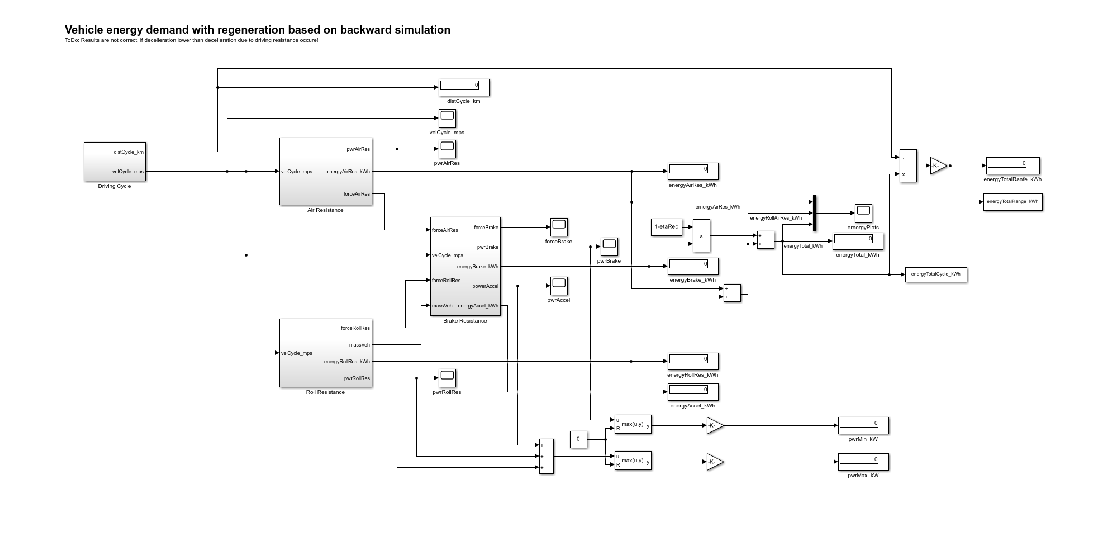

figure
snapshotModel('EnergyDemandBackward')

sim('EnergyDemandBackward')

Dadurch ergibt sich ein Energiebedarf von:

energyVeh2Miles_kWh = energyTotalRange_kWh.Data(end)

energyVeh2Miles_kWh = 6.3024

energyBatCycle_kWh = energyVeh2Miles_kWh/etaElecDrive/etaBatCha

energyBatCycle_kWh = 8.0917

## **Batterie**

Die Batterie soll aus Zellen / Modulen eines Zulieferers aufgebaut werden. Relevante Daten sind:

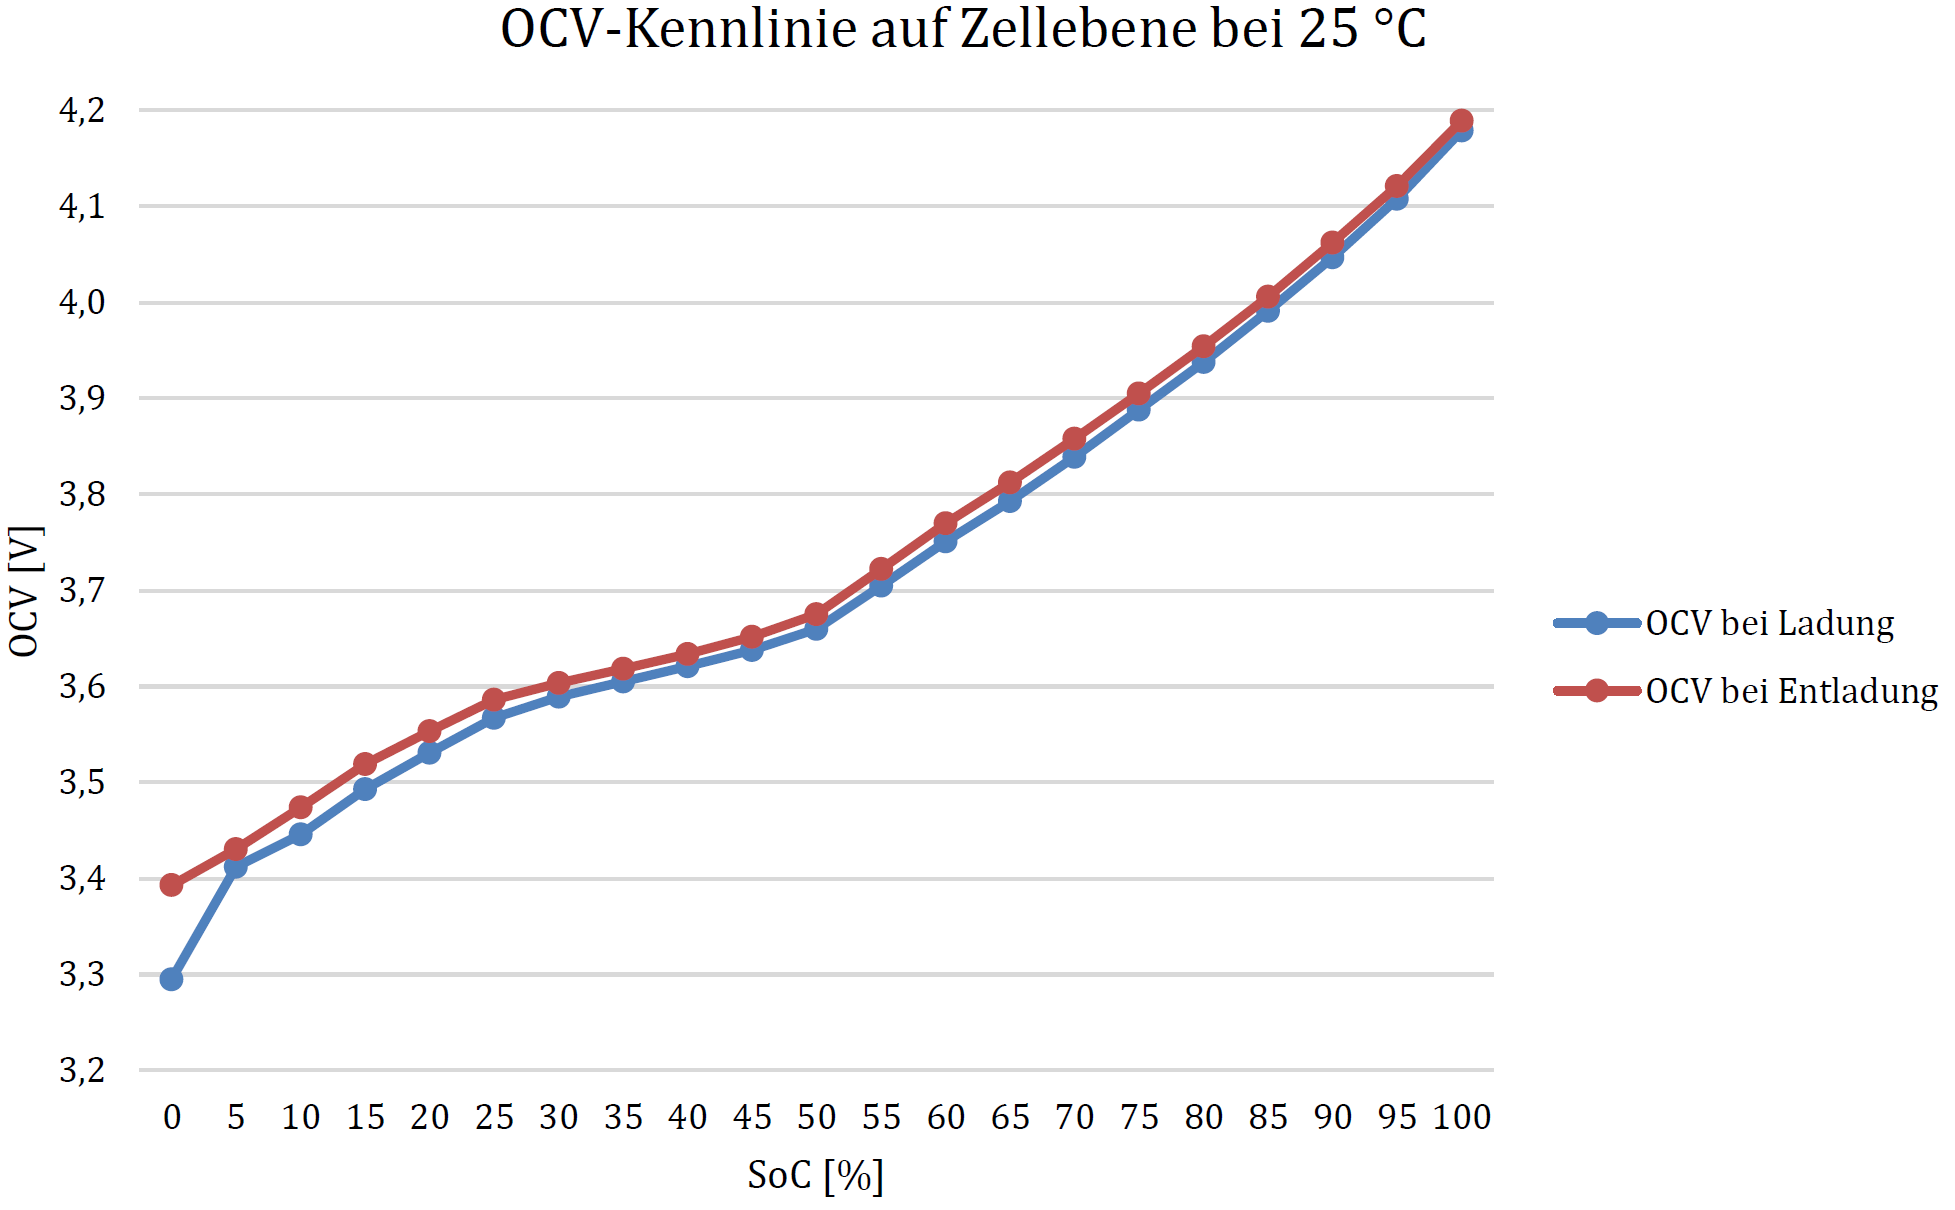

capCell_Ah =    4.6;
volCell =       3.8;
resIntBat =     0.007;
facBatSwing =   0.9;

Unter Berücksichtigung eines Batterie-Swings ergibt sich eine Batteriegröße von:

energyBat_kWh = energyBatCycle_kWh;
energyBatDes_kWh = energyBat_kWh/facBatSwing

energyBatDes_kWh = 8.9908

Wenn die Motoren am Eckpunkt mit 48V betrieben werden sollen benötigt die Batterie eine Leerlaufspannung von 

volBatNoLoad = volMotNom + numMot*resIntBat*trqMotCont/constMotTrq

volBatNoLoad = 51.9200

Dimensionierung

numSer = volBatNoLoad/volCell

numSer = 13.6632

capBat_Ah = energyBatDes_kWh*1000/volBatNoLoad

capBat_Ah = 173.1662

numPar = capBat_Ah/capCell_Ah

numPar = 37.6448

numCell= numSer*numPar

numCell = 514.3473

Anhand der Stromgrenzend der Batterie können vermutlich nur zwei Motoren pro Batterie versorgt werden: